## Resistor-Capacitor circuits

### 1. Capacitive low-pass filter

circuit = Circuit('circuits/passive/c2_rc_low_pass.txt');
circuit.list

ans =     'Vin 1 0 DC 5
     R1 1 2 1000
     C1 2 0 0.0001
     '


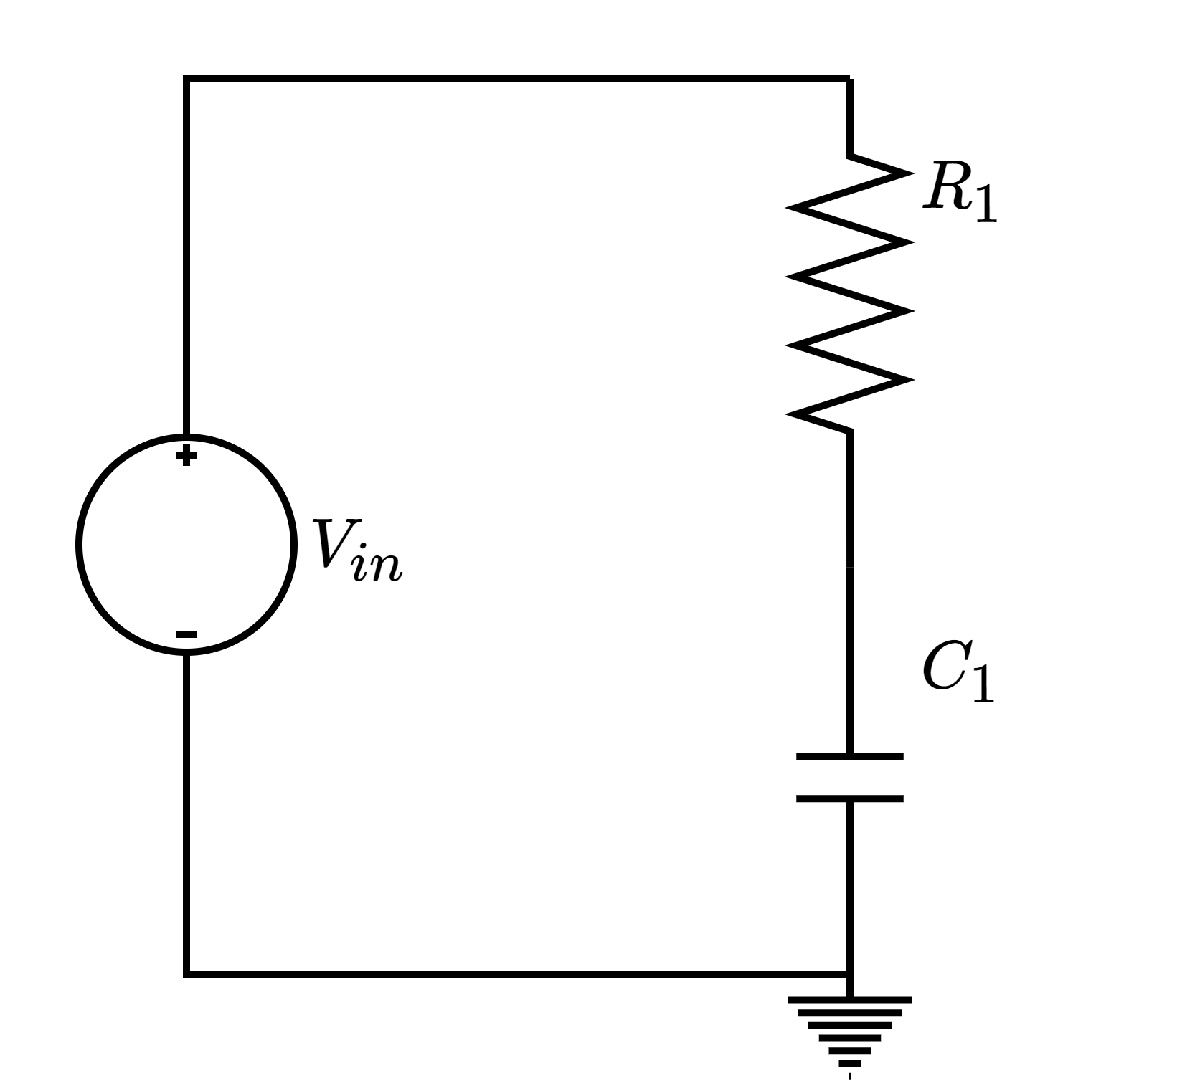

ELAB.analyze(circuit)

Symbolic analysis successful (0.29412 sec).


Maybe you want expressions for node voltages.

circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vin}\\ v_{2}=\frac{\mathrm{Vin}}{C_{1}\,R_{1}\,s+1} \end{array}\right)$$

Or the numerical currents for all elements in this particular circuit in relation to the s-domain.

ELAB.evaluate(circuit)


Numerical evaluation successful (0.0490318 sec).


ELAB.
circuit.numerical_element_currents

$$ans = \left(\begin{array}{c} i_{\mathrm{R1}}=\frac{s}{2000\,\left(\frac{s}{10}+1\right)}\\ i_{\mathrm{C1}}=\frac{5}{\frac{s}{100000}+\frac{1}{10000}} \end{array}\right)$$

Say we want the numerical transfer function, where the output is the voltage across the capacitor.

TF = ELAB.ec2tf(circuit, 1, 2)

Transfer function object created successfully (6.486560e-02 sec).

TF =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



Matlab can then be used to visualize the circuit behavior as with any other system. Plotting the Bode diagram, we see that this is infact a low-pass-filter.

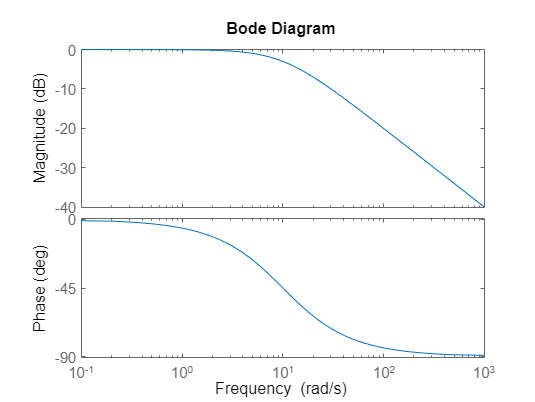

bode(TF)

### 2. Capacitive high-pass filter

We can repeat the process with a variation of the circuit, where the capacitor comes before the resistor.

circuit = Circuit('circuits/passive/c3_rc_high_pass.txt');
circuit.list

ans =     'Vin 1 0 DC 5
     R1 2 0 1000
     C1 1 2 0.0001
     '


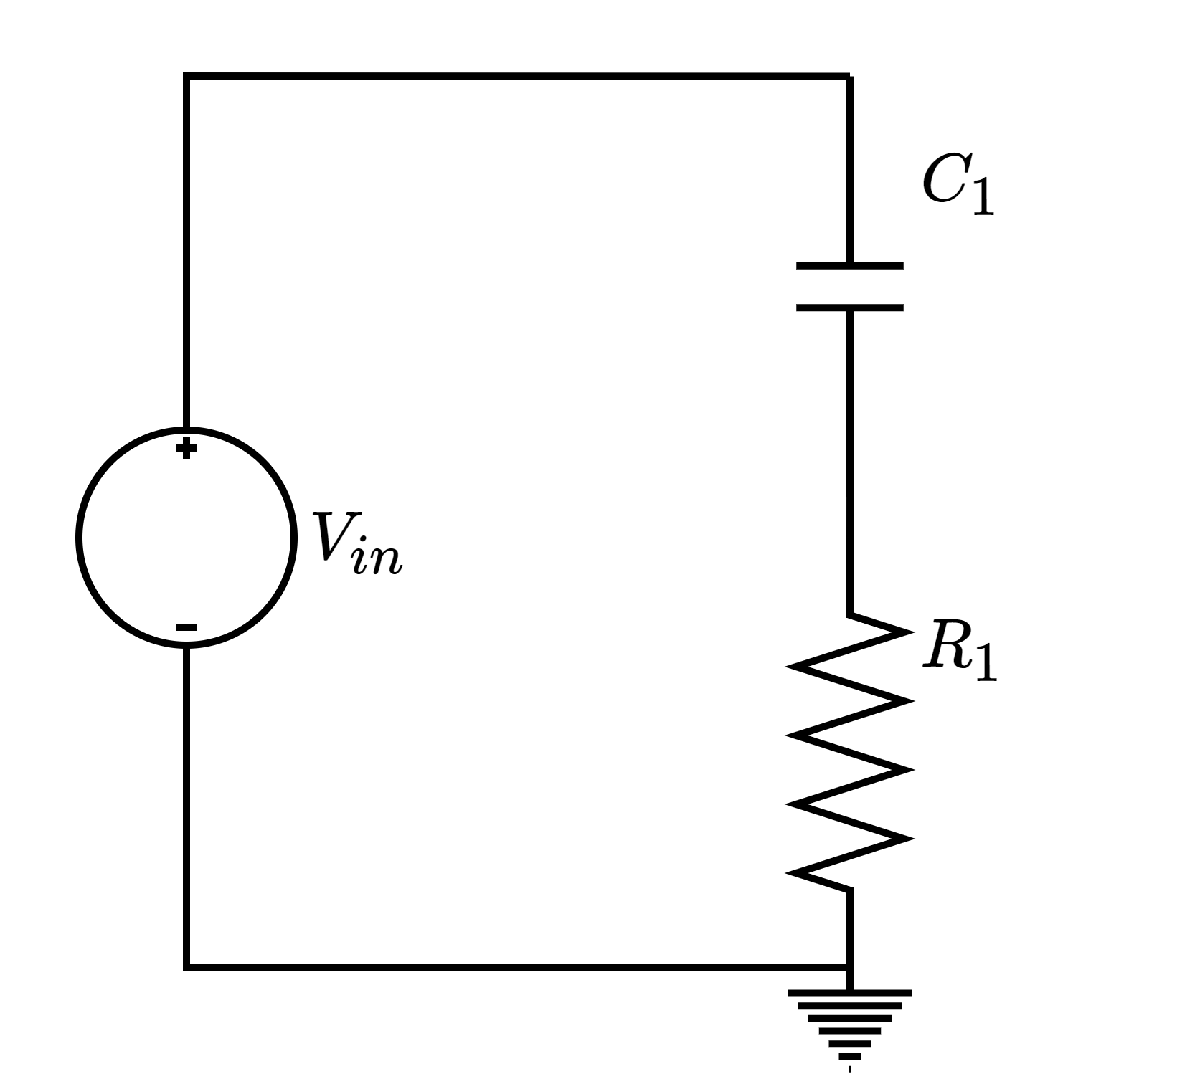

ELAB.analyze(circuit)

Symbolic analysis successful (0.169788 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vin}\\ v_{2}=\frac{C_{1}\,R_{1}\,\mathrm{Vin}\,s}{C_{1}\,R_{1}\,s+1} \end{array}\right)$$

TF = ELAB.ec2tf(circuit, 1, 2);

Numerically evaluating circuit.

Numerical evaluation successful (0.0411536 sec).
Transfer function object created successfully (7.335670e-02 sec).


Plotting the Bode diagram, we see that this rc-configuration acts as a high-pass filter.

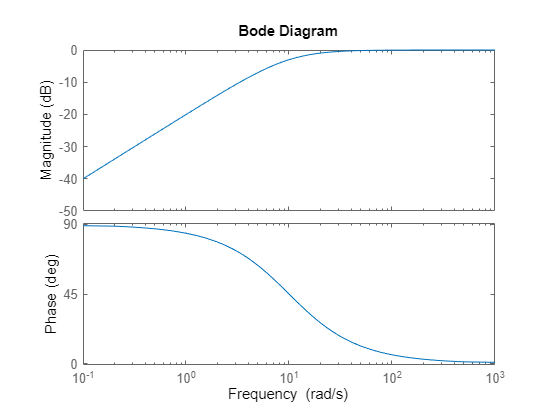

bode(TF)